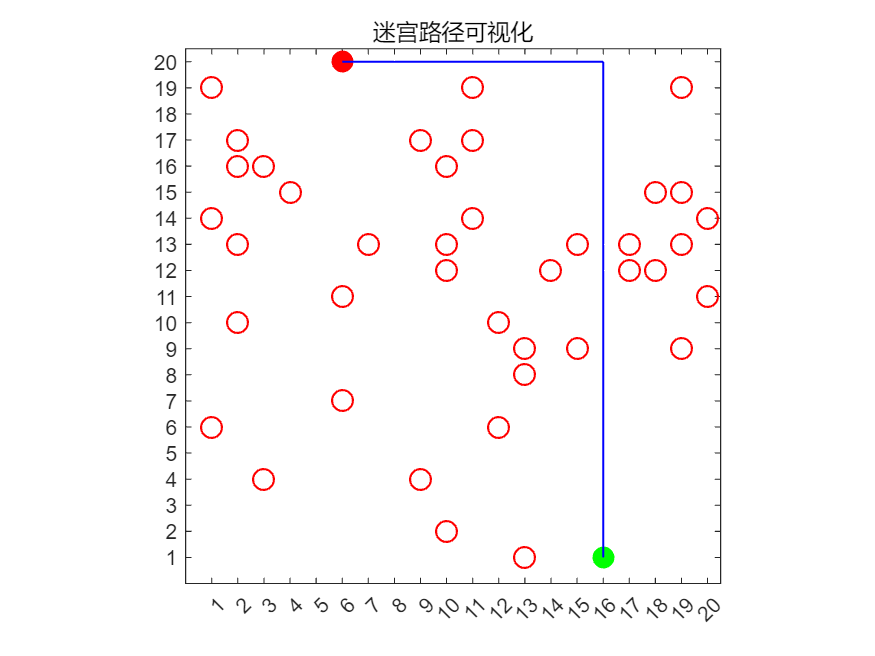

clc;clear;close all;
findPath(20,0.1);

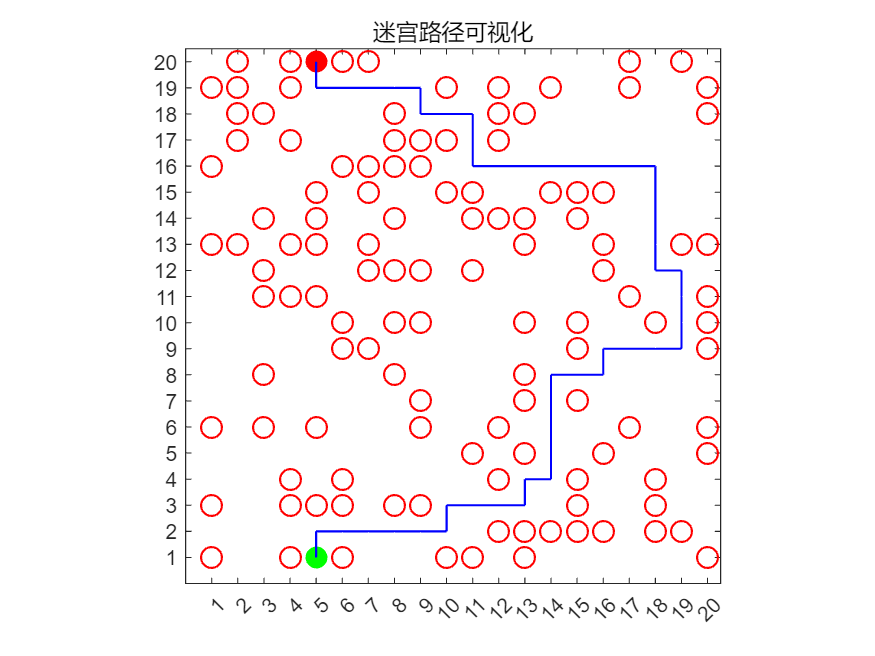

findPath(20,0.3);

没有找到路径


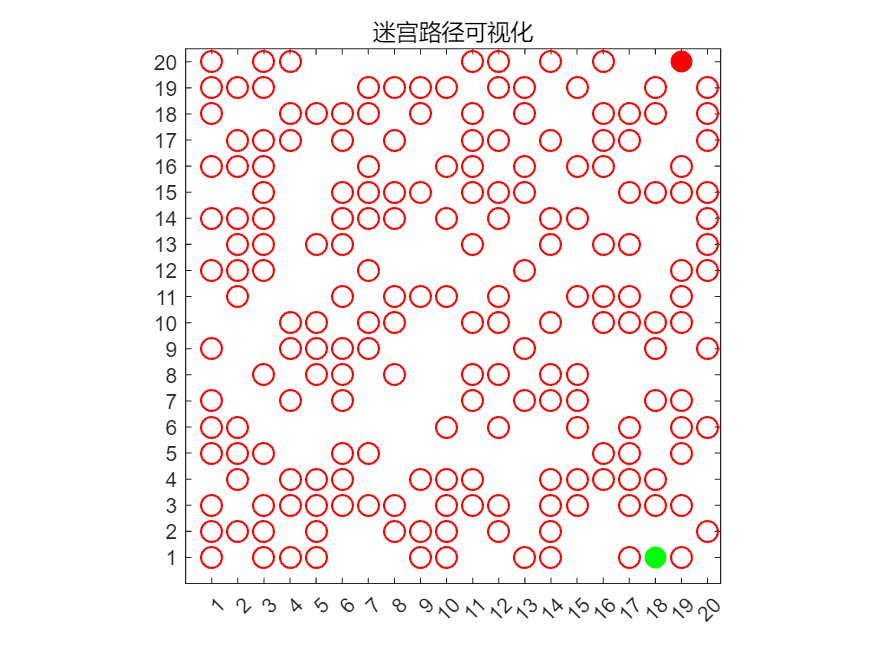

findPath(20,0.5)

function findPath(N, barrierrate)
    grid = zeros(N, N);
    num_barrier = round(N * N * barrierrate);
    barrier = randperm(N * N, num_barrier);
    grid(barrier) = 1;
    
    startnode = [1, randi(N)];
    endnode = [N, randi(N)];
    grid(startnode(1), startnode(2)) = 0;
    grid(endnode(1), endnode(2)) = 0;
    
    visited = false(N, N);
    visited(startnode(1), startnode(2)) = true;

    queue = {startnode};
    prev = zeros(N, N, 2);
    
    while ~isempty(queue)
        current = queue{1};  
        queue = queue(2:end);  
        
        if isequal(current, endnode)
            break;
        end

        neighbors = getNeighbors(current, N);
        for i = 1:size(neighbors, 1)
            neighbor = neighbors(i, :);
  
            if ~visited(neighbor(1), neighbor(2)) && grid(neighbor(1), neighbor(2)) == 0
                visited(neighbor(1), neighbor(2)) = true;
                queue{end + 1} = neighbor;  
                prev(neighbor(1), neighbor(2), :) = current;
            end
        end
    end
    
    path = [];
    if visited(endnode(1), endnode(2))
        current = endnode;
        while ~isequal(current, startnode)
            path = [current; path];  
            current = squeeze(prev(current(1), current(2), :))';
        end
        path = [startnode; path]; 
    else
        disp('没有找到路径');
    end

    figure;
    hold on;
    
    [row, col] = find(grid == 1);
    scatter(col, row, 100, 'r', 'o', 'LineWidth', 1);  
    
    plot(startnode(2), startnode(1), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');  
    plot(endnode(2), endnode(1), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');  
    
    if ~isempty(path)
        for i = 1:size(path, 1)-1
            plot([path(i, 2), path(i+1, 2)], [path(i, 1), path(i+1, 1)], 'b-', 'LineWidth', 1);  
        end
    end

    axis([0 N+0.5 0 N+0.5]);

    xticks(1:N);
    yticks(1:N);

    axis square;
    box on;
    title('迷宫路径可视化');
    
    hold off;
end

function neighbors = getNeighbors(current, N)
    neighbors = [];
    if current(1) > 1
        neighbors = [neighbors; current(1)-1, current(2)];  
    end
    if current(1) < N
        neighbors = [neighbors; current(1)+1, current(2)]; 
    end
    if current(2) > 1
        neighbors = [neighbors; current(1), current(2)-1];
    end
    if current(2) < N
        neighbors = [neighbors; current(1), current(2)+1];
    end
end

